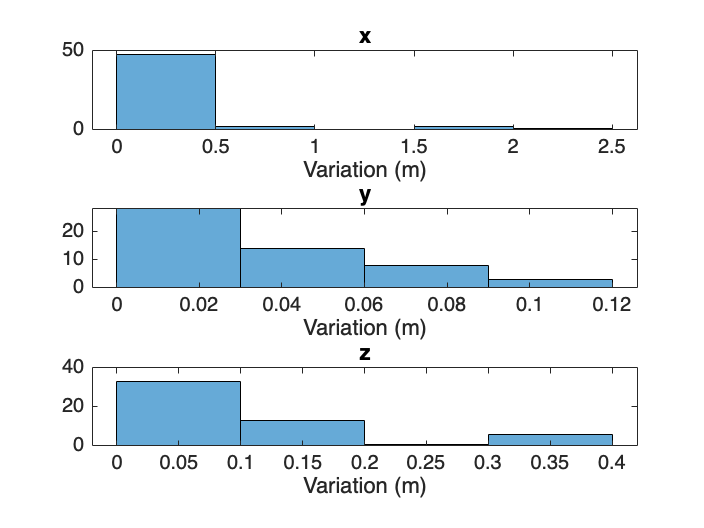

fiducial_variation = readtable('variation_outdoor.txt');

% Plot the fiducial variation histogram for each x,y,z
figure;
subplot(3,1,1)
histogram(fiducial_variation.x)
xlabel('Variation (m)')
title('x')
subplot(3,1,2)
histogram(fiducial_variation.y)
xlabel('Variation (m)')
title('y')
subplot(3,1,3)
histogram(fiducial_variation.z)
xlabel('Variation (m)')
title('z')

% Save figure as png
saveas(gcf, 'fiducial_variation_outdoors.png')

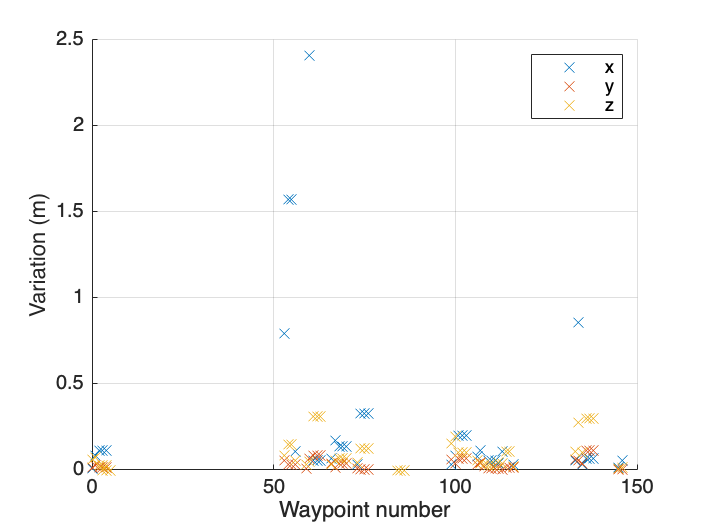


% Plot the fiducial variation against waypoint number, on the same axes
figure;
hold on
grid on
plot(fiducial_variation.waypoint, fiducial_variation.x, 'x')
plot(fiducial_variation.waypoint, fiducial_variation.y, 'x')
plot(fiducial_variation.waypoint, fiducial_variation.z, 'x')
legend('x', 'y', 'z')
xlabel('Waypoint number')
ylabel('Variation (m)')

% Save figure as png
saveas(gcf, 'fiducial_variation_outdoors_waypoint.png')